## 3D plot for visual comparison: Mitracks3D vs YOLOv8x

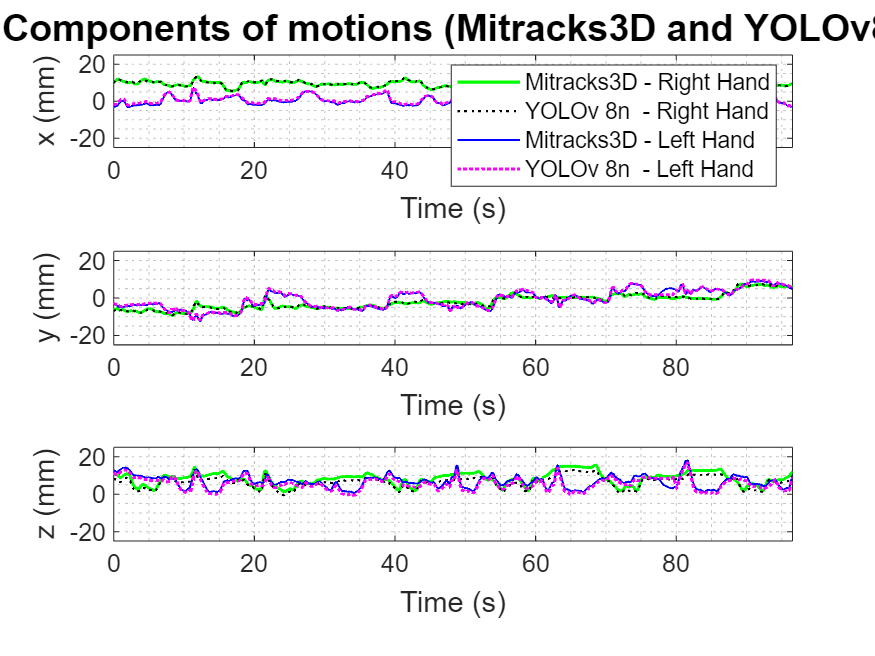

% Add this script to the MATLAB's path
% Both ExampleData_Mitracks.mat and ExampleData_YOLO.mat must be in the
% script's directory

close all; clearvars; clc;

if matlab.desktop.editor.isEditorAvailable
    full_path = matlab.desktop.editor.getActiveFilename;
else
    full_path = mfilename('fullpath');
end 
                                           
[path_script, ~, ~] = fileparts(full_path); 


load(horzcat(path_script, '\ExampleData_Mitracks3D.mat'));
load(horzcat(path_script, '\ExampleData_YOLOv8n.mat')); % You can select YOLOv8n or YOLOv8m
timeT = MuestraTR_Mitracks(:,7);

figure
 subplot(3,1,1)
    plot(timeT, MuestraTR_Mitracks(:,1) ,'g-', 'LineWidth', 1.5, 'DisplayName', 'Mitracks3D - Right Hand')
    ax = gca; 
    set(ax, 'FontSize', 12); 
    title('Components of motions (Mitracks3D and YOLOv8)', 'FontSize', 18)
    xlabel('Time (s)', 'FontSize', 14), ylabel('x (mm)', 'FontSize', 14)
    ylim([-25 25])
    xlim([0 timeT(end)] )
    grid minor
    hold on
    plot(timeT, MuestraTR_YOLO(:,1) ,'k:', 'LineWidth', 1.1, 'DisplayName', 'YOLOv 8n  - Right Hand')

    plot(timeT, MuestraTR_Mitracks(:,4) ,'b-', 'LineWidth', 1, 'DisplayName', 'Mitracks3D - Left Hand')
    plot(timeT, MuestraTR_YOLO(:,4) ,'m:', 'LineWidth', 1.5, 'DisplayName', 'YOLOv 8n  - Left Hand')
  
    legend('Location','southeast')

 subplot(3,1,2)
    plot(timeT, MuestraTR_Mitracks(:,2) ,'g-', 'LineWidth', 1.5, 'DisplayName', 'Mitracks3D - Right Hand')
    ax = gca; 
    set(ax, 'FontSize', 12); 
    xlabel('Time (s)', 'FontSize', 14), ylabel('y (mm)', 'FontSize', 14)
    ylim([-25 25])
    xlim([0 timeT(end)] )
    grid minor
    hold on
    plot(timeT, MuestraTR_YOLO(:,2) ,'k:', 'LineWidth', 1.1, 'DisplayName', 'YOLOv 8n  - Right Hand')

    plot(timeT, MuestraTR_Mitracks(:,5) ,'b-', 'LineWidth', 1, 'DisplayName', 'Mitracks3D - Left Hand')
    plot(timeT, MuestraTR_YOLO(:,5) ,'m:', 'LineWidth', 1.5, 'DisplayName', 'YOLOv 8n  - Left Hand')

 subplot(3,1,3)
    plot(timeT, MuestraTR_Mitracks(:,3) ,'g-', 'LineWidth', 1.5, 'DisplayName', 'Mitracks3D - Right Hand')
    ax = gca; 
    set(ax, 'FontSize', 12); 
    xlabel('Time (s)', 'FontSize', 14), ylabel('z (mm)', 'FontSize', 14)
    ylim([-25 25])
    xlim([0 timeT(end)] )
    hold on
    grid minor

    plot(timeT, MuestraTR_YOLO(:,3) ,'k:', 'LineWidth', 1.1, 'DisplayName', 'YOLOv 8n  - Right Hand')

    plot(timeT, MuestraTR_Mitracks(:,6) ,'b-', 'LineWidth', 1, 'DisplayName', 'Mitracks3D - Left Hand')
    plot(timeT, MuestraTR_YOLO(:,6) ,'m:', 'LineWidth', 1.5, 'DisplayName', 'YOLOv 8n  - Left Hand')